# ME5554/AOE5754/ECE5754 Applied Linear Systems

# Homework 4

Sam Kramer

September 18th, 2023

## Problem 1.

On L4/S21, a matrix exponential solution was provided for the 2nd order state equation on that same slide.  For this problem, derive an expression for the State Transition Matrix (i.e. matrix exponential) using the Laplace Method.

% --Setup situation
    clear; clc; format compact; close all;

% --Setup eqation
    syms x_dot_1 x_dot_2 x_1 x_2 u s;
    x_dot = [x_dot_1; x_dot_2];
    x = [x_1; x_2];
    A = [-3 1;
          0 -10];
    B = [0; 1];
    state = A*x + B*u

$$state = \left(\begin{array}{c} x_{2}-3\,x_{1}\\ u-10\,x_{2} \end{array}\right)$$

% --Finding the matrix exponential
    C = s*eye(2) - A;
    C_inv = inv(C);
    D = C_inv * B * u;
    IC_sol = ilaplace(C_inv)

$$IC\_sol = \left(\begin{array}{cc} {\mathrm{e}}^{-3\,t} & \frac{{\mathrm{e}}^{-3\,t}}{7}-\frac{{\mathrm{e}}^{-10\,t}}{7}\\ 0 & {\mathrm{e}}^{-10\,t} \end{array}\right)$$

This is the e^(At) solution or the matrix exponential.

% --Proof
    expm(A)

ans =     0.0498    0.0071
         0    0.0000


Which is the numerical answer to the solution that I gave above.

## Problem 2.

An LTI dynamic system is defined by the following coupled ODEs:

${\dot{x} }_1 =\omega x_2$   and   ${\dot{x} }_2 =-\omega x_1$,  where  $\omega =12\ldotp 87$

a)  Derive an expression for the State Transition matrix $\Phi \left(t,t_0 \right)$ for this system.  Do NOT assume that $t_0 =0$!

% --Setup
    clear; clc; close all; format compact;

% --Create dynamic system
    syms omega x_1 x_2 s t t_0 u 
    A = [0 omega;
        -omega 0];
    x = [x_1;
         x_2];
    B = [0;
         0];
    C = [0;
         0];
    D = [0;
         0];
    solution = A*x + B*u

$$solution = \left(\begin{array}{c} \omega \,x_{2}\\ -\omega \,x_{1} \end{array}\right)$$

% --Finding the matrix exponential
    C = s*eye(2) - A;
    C_inv = inv(C);
    eAt = ilaplace(C_inv)

$$eAt = \left(\begin{array}{cc} \cos\left(\omega \,t\right) & \sin\left(\omega \,t\right)\\ -\sin\left(\omega \,t\right) & \cos\left(\omega \,t\right) \end{array}\right)$$

This is the solution that we have for e^(At)

b)  You are given that at time $t_1 =0\ldotp 1$ seconds, the state vector is:  ${\mathbf{x}}_1 =\left\lbrack \begin{array}{c}
4\\
3
\end{array}\right\rbrack$.  First, use the result from 2a to compute AND display the numerical state transition matrix which transforms the state from $t_1 =0\ldotp 1$ seconds to $t_2 =0\ldotp 15$ seconds.  

% --Compute C vector that gets us [4; 3]
    x1 = [4; 3];
    C = eAt\x1

$$C = \left(\begin{array}{c} \frac{4\,\cos\left(\omega \,t\right)-3\,\sin\left(\omega \,t\right)}{{\cos\left(\omega \,t\right)}^{2}+{\sin\left(\omega \,t\right)}^{2}}\\ \frac{3\,\cos\left(\omega \,t\right)+4\,\sin\left(\omega \,t\right)}{{\cos\left(\omega \,t\right)}^{2}+{\sin\left(\omega \,t\right)}^{2}} \end{array}\right)$$

% --Proof that C is correct
    B = eAt*C;
    t = 0.1;
    omega = 12.87;
    x1 = simplify(subs(B))

$$x1 = \left(\begin{array}{c} 4\\ 3 \end{array}\right)$$

% --Calculate x2 at time t2
    t = 0.15;
    x2 = eAt*C;
    x2 = simplify(subs(x2))

$$x2 = \left(\begin{array}{c} 4\\ 3 \end{array}\right)$$

Then use this result to determine the state vector ${\mathbf{x}}_2$ at time $t_2$.  

c)  Use the Matlab `EXPM()` function to solve problem 2b, and confirm your answers.

% --Proof part A
    expm(A)

$$ans = \left(\begin{array}{cc} \frac{{\mathrm{e}}^{-\omega \,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{\omega \,\mathrm{i}}}{2} & \frac{{\mathrm{e}}^{-\omega \,\mathrm{i}}\,\mathrm{i}}{2}-\frac{{\mathrm{e}}^{\omega \,\mathrm{i}}\,\mathrm{i}}{2}\\ -\frac{{\mathrm{e}}^{-\omega \,\mathrm{i}}\,\mathrm{i}}{2}+\frac{{\mathrm{e}}^{\omega \,\mathrm{i}}\,\mathrm{i}}{2} & \frac{{\mathrm{e}}^{-\omega \,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{\omega \,\mathrm{i}}}{2} \end{array}\right)$$

This is the proof that my answer for part A is correct

% --Proof part B
    eAt

$$eAt = \left(\begin{array}{cc} \cos\left(\omega \,t\right) & \sin\left(\omega \,t\right)\\ -\sin\left(\omega \,t\right) & \cos\left(\omega \,t\right) \end{array}\right)$$

    subs(eAt)*0.1

$$ans = \left(\begin{array}{cc} \frac{\cos\left(\frac{3861}{2000}\right)}{10} & \frac{\sin\left(\frac{3861}{2000}\right)}{10}\\ -\frac{\sin\left(\frac{3861}{2000}\right)}{10} & \frac{\cos\left(\frac{3861}{2000}\right)}{10} \end{array}\right)$$

    simplify(expm(ans))

$$ans = \left(\begin{array}{cc} \cos\left(\frac{\sin\left(\frac{3861}{2000}\right)}{10}\right)\,{\mathrm{e}}^{\frac{\cos\left(\frac{3861}{2000}\right)}{10}} & \sin\left(\frac{\sin\left(\frac{3861}{2000}\right)}{10}\right)\,{\mathrm{e}}^{\frac{\cos\left(\frac{3861}{2000}\right)}{10}}\\ -\sin\left(\frac{\sin\left(\frac{3861}{2000}\right)}{10}\right)\,{\mathrm{e}}^{\frac{\cos\left(\frac{3861}{2000}\right)}{10}} & \cos\left(\frac{\sin\left(\frac{3861}{2000}\right)}{10}\right)\,{\mathrm{e}}^{\frac{\cos\left(\frac{3861}{2000}\right)}{10}} \end{array}\right)$$

Which I think is going to be the solution once solved numerically.

## Problem 3.

Use the results from Problem 2 above to demonstrate the following property of the State Transition Matrix:

${\mathbf{x}}_3 =\Phi \left(t_3 ,t_1 \right){\mathbf{x}}_1$  is equivalent to  ${\mathbf{x}}_3 =\Phi \left(t_3 ,t_2 \right)\Phi \left(t_2 ,t_1 \right){\mathbf{x}}_1$

where $t_1 =0\ldotp 1$, $t_2 =0\ldotp 15$, and $t_3 =0\ldotp 2$, and ${\mathbf{x}}_n \equiv x\left(t_n \right)$

For these particular time values, also show that:  ${\mathbf{x}}_3 =\Phi^2 \left(t_2 ,t_1 \right){\mathbf{x}}_1$

You can solve this problem analytically, numerically, or both.

% --Phi(1,0)
    t = 0.1;
    omega = 12.87;
    eAt1 = subs(eAt);

% --Phi(2,1)
    t = 0.15;
    eAt2 = subs(eAt);

% --Phi(3,2)
    t = 0.2;
    eAt3 = subs(eAt);

% --X3 first one
    X3_1 = eAt3*x1

$$X3\_1 = \left(\begin{array}{c} 4\,\cos\left(\frac{1287}{500}\right)+3\,\sin\left(\frac{1287}{500}\right)\\ 3\,\cos\left(\frac{1287}{500}\right)-4\,\sin\left(\frac{1287}{500}\right) \end{array}\right)$$


% --X3 second one
    x3_2 = simplify(eAt32*eAt21*x1)

$$x3\_2 = \left(\begin{array}{c} \frac{12\,\cos\left(\frac{1287}{1000}\right)-14\,\cos\left(\frac{3861}{500}\right)+2}{\cos\left(\frac{1287}{1000}\right)-\cos\left(\frac{9009}{1000}\right)}\\ -\frac{14\,\cos\left(\frac{3861}{500}\right)-16\,\cos\left(\frac{1287}{1000}\right)+2}{\cos\left(\frac{1287}{1000}\right)-\cos\left(\frac{9009}{1000}\right)} \end{array}\right)$$

% --Showing phi21^2 works
    x3_3 = simplify((eAt21^2)*x1)

$$x3\_3 = \left(\begin{array}{c} \frac{14\,\cos\left(\frac{1287}{200}\right)+2\,\cos\left(\frac{1287}{1000}\right)-16}{\cos\left(\frac{3861}{500}\right)-1}\\ -\frac{2\,\cos\left(\frac{1287}{1000}\right)-14\,\cos\left(\frac{1287}{200}\right)+12}{\cos\left(\frac{3861}{500}\right)-1} \end{array}\right)$$

## Problem 4.

The dynamic system shown in Figure 1.16 of the course textbook is associated with Continuing Exercise (CE3).  This dynamic system is a basic DC servomotor with a mechanical load.  The numerical parameters for this dynamic system are provided in Table 2.5 of the textbook.  In Problem CE2.3a, assume that the input is the armature voltage $v_A \left(t\right)$, and the output is the load shaft angle $\theta_L \left(t\right)$.  The complete state space representation is shown on page 104 of the course textbook.  For the homogeneous system (i.e. assume zero input), use the Matlab `EXPM` function to numerically evaluate the state transition matrix over a time interval from 0 to 1s.  Plot your results on a properly annotated plot.  You will have to determine an appropriate time sampling resolution for this data.

Hint:  The State Transition matrix is a square matrix of time-domain functions.  You will need to plot each element of this matrix in a grid of subplots where each subplot corresponds to the *ij* entry of the matrix.  In each subplot, you will plot the value of that element vs. time.

Make sure you properly annotate each subplot with grid lines and a label indicating which element of the matrix the plot is for, i.e. $\Phi_{ij}$

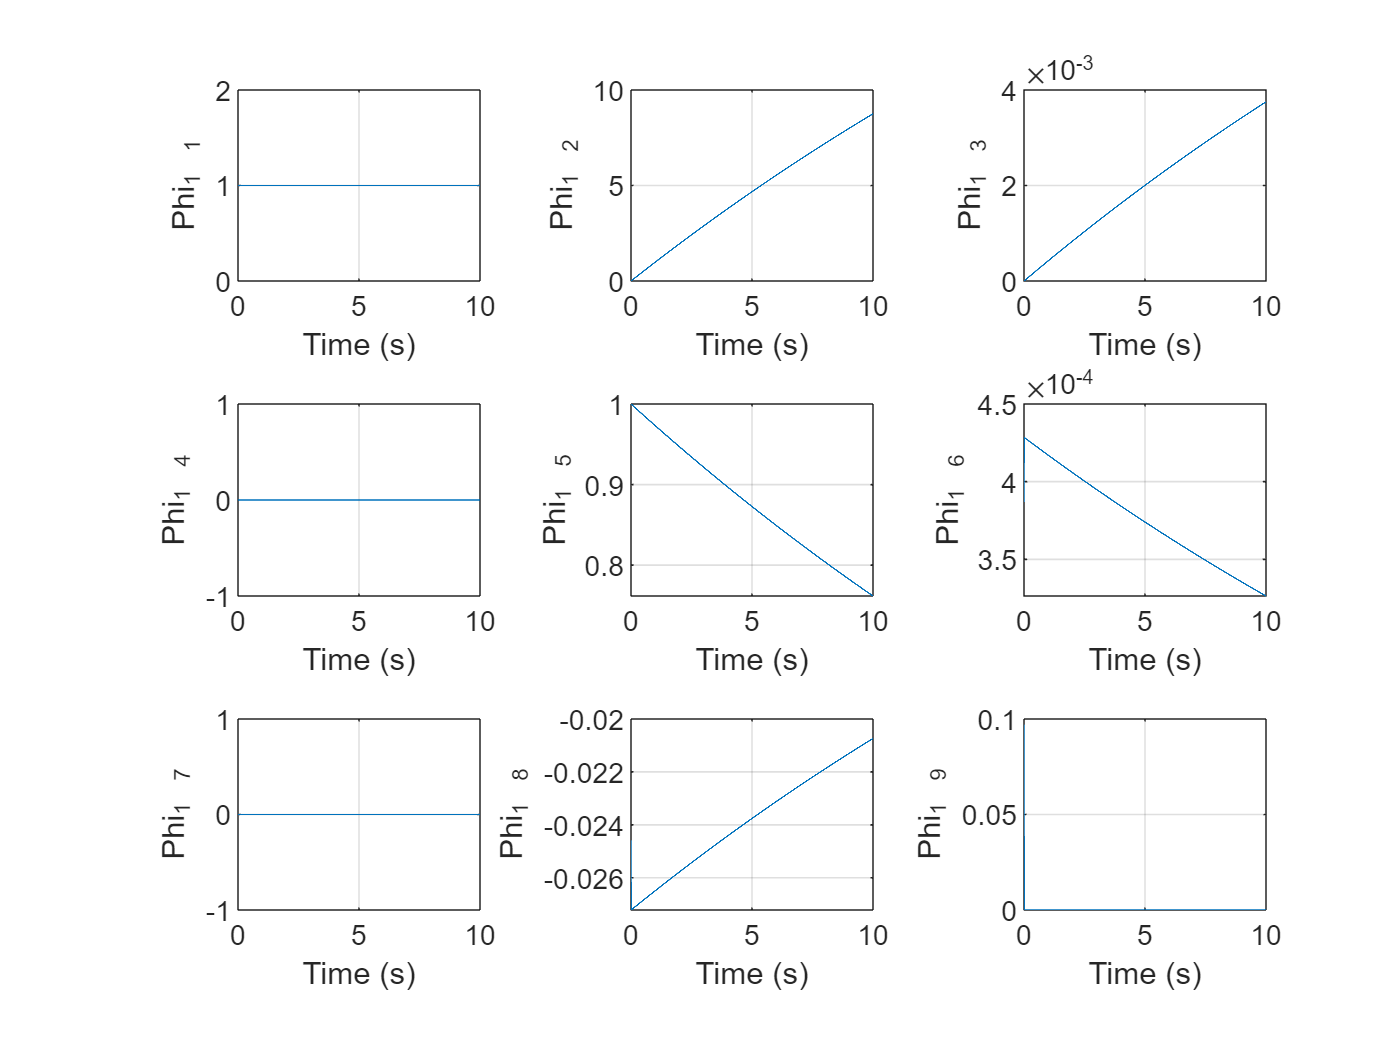

% --Setup
    clear; clc; format compact; close all;

% --Describe parameters
    L = 0.0006;
    R = 1.40;
    b = 0.00013;
    J = 1;
    kt = 4.375;
    kb = 0.00867;
    n = 200;

% --Describe the state space representation
    A = [0 1 0;
         0 0 1;
         0 -(R*b + kt*kb)/(L*J) -(L*b + R*J)/(L*J)];

% --Definition of parameters
    fs = 1000;
    maxt = 10;
    t = 0:1/fs:maxt;
    phi = zeros(3,3,fs);
    for i = 1:(fs*maxt) + 1
        phi(:,:,i) = expm(A*t(i));
    end
    
% --Plot solutions
    for i = 1:3
        subplot(3,3,1*i)
        x = squeeze(phi(1,i,2:end))';
        plot(t(2:end),x)
            label = sprintf("Phi_{1%3.0f}",i);
            ylabel(label)
            xlabel('Time (s)')
            grid on

        subplot(3,3,i + 3)
        x = squeeze(phi(2,i,2:end))';
        plot(t(2:end),x)
            label = sprintf("Phi_{1%3.0f}",i+3);
            ylabel(label)
            xlabel('Time (s)')
            grid on

        subplot(3,3,i + 6)
        x = squeeze(phi(3,i,2:end))';
        plot(t(2:end),x)
            label = sprintf("Phi_{1%3.0f}",i+6);
            ylabel(label)
            grid on
            xlabel('Time (s)')
    end

## Problem 5.

For Problem NE 2.4 in the course textbook, use the Matlab EXPM function to numerically evaluate the state transition matrix from 0 to 1 seconds with a time resolution of 0.1 second.  Also numerically evaluate the state transition matrix using a finite series expansion as defined in the notes.  Determine the number of terms you need to keep in the expansion in order to ***reasonably*** match the results of EXPM.  Demonstrate your result by comparing the elements of the state transition matrix from EXPM to the series expansion.  There should be four subplots in a grid, where each subplot represents the appropriate element of the state transition matrix.

% --Setup system
    A = [0 1;
        -6 -12];
    x_0 = [2;
           1];

% --Calculate eAt numerically
    syms s
    eAt = ilaplace(inv(s*eye(2) - A))

$$eAt = \begin{array}{l} \left(\begin{array}{cc} {\mathrm{e}}^{-6\,t}\,\left(\cosh\left(\sqrt{30}\,t\right)+\frac{\sqrt{30}\,\sinh\left(\sqrt{30}\,t\right)}{5}\right) & \frac{\sigma_{1}}{30}\\ -\frac{\sigma_{1}}{5} & {\mathrm{e}}^{-6\,t}\,\left(\cosh\left(\sqrt{30}\,t\right)-\frac{\sqrt{30}\,\sinh\left(\sqrt{30}\,t\right)}{5}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{30}\,{\mathrm{e}}^{-6\,t}\,\sinh\left(\sqrt{30}\,t\right) \end{array}$$

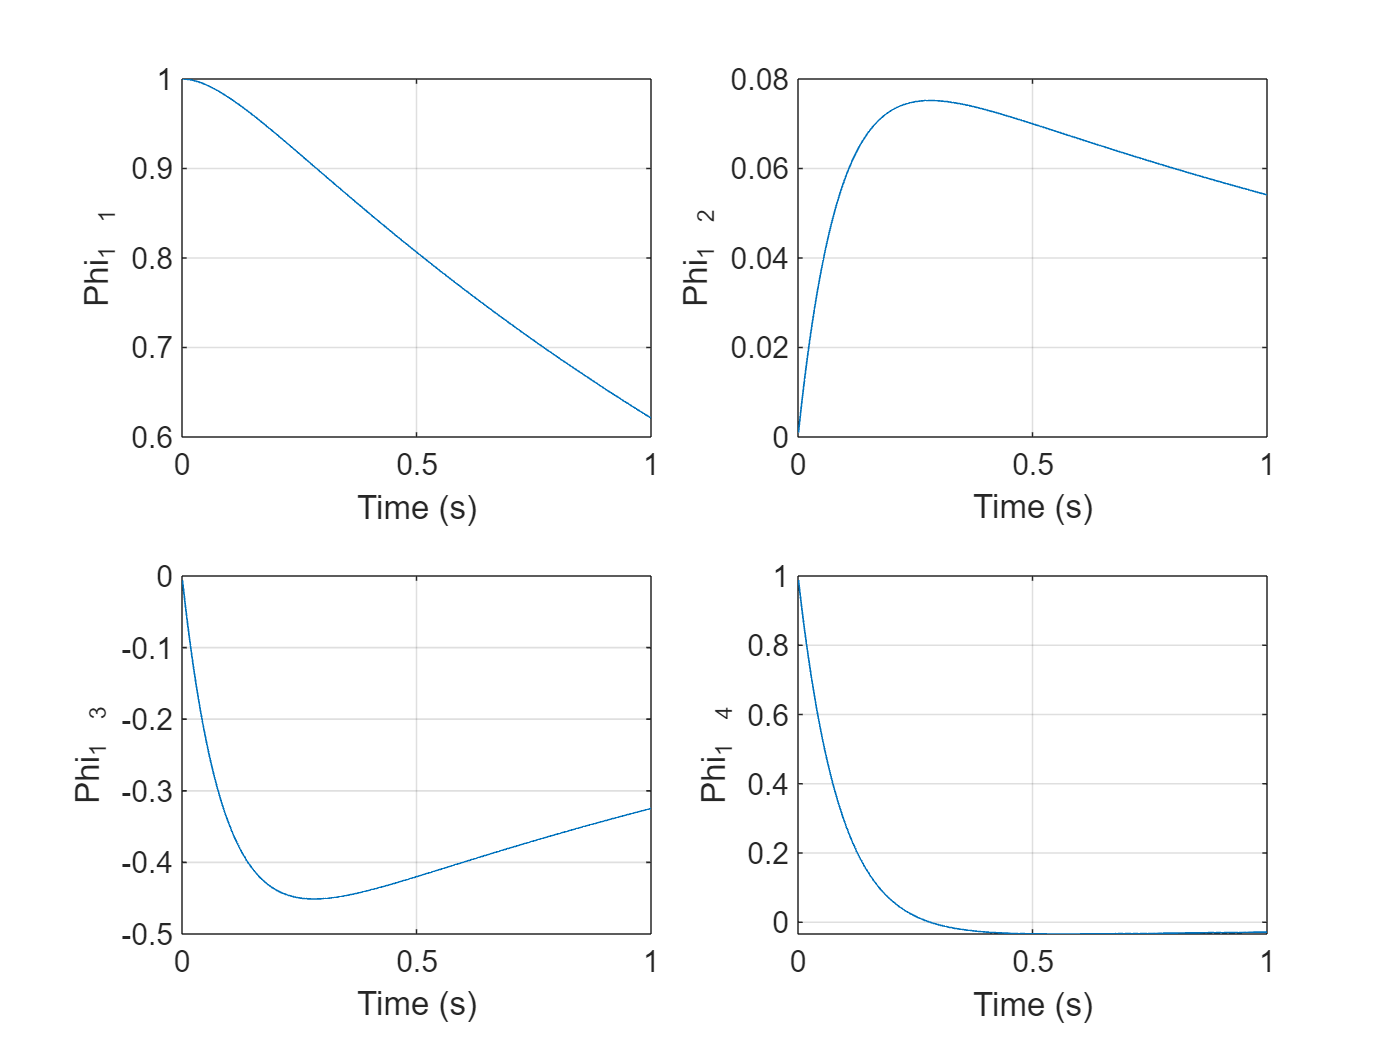

% --Definition of parameters
    fs = 1000;
    maxt = 1;
    t = 0:1/fs:maxt;
    phi = zeros(2,2,fs);
    for i = 1:(fs*maxt) + 1
        phi(:,:,i) = expm(A*t(i));
    end

% --Plot solutions
    for i = 1:2
        subplot(2,2,1*i)
        x = squeeze(phi(1,i,2:end))';
        plot(t(2:end),x)
            label = sprintf("Phi_{1%3.0f}",i);
            ylabel(label)
            xlabel('Time (s)')
            grid on

        subplot(2,2,i + 2)
        x = squeeze(phi(2,i,2:end))';
        plot(t(2:end),x)
            label = sprintf("Phi_{1%3.0f}",i+2);
            ylabel(label)
            xlabel('Time (s)')
            grid on
    end

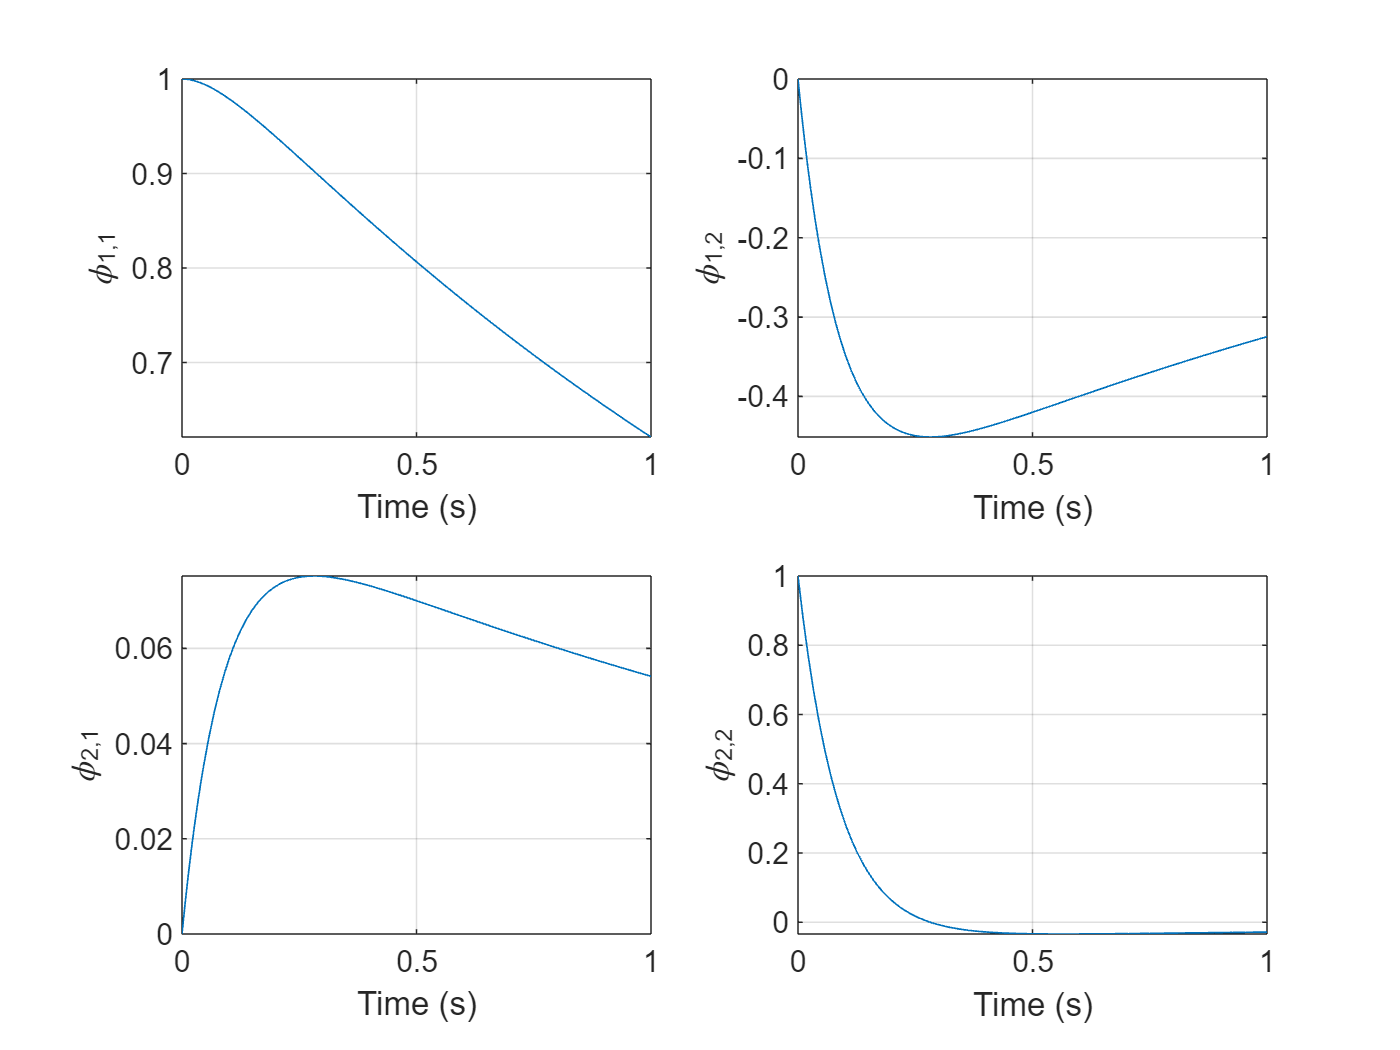

% --Finite series expansion method
    syms t
    terms = 50;
    eAt = eye(2);

    for i = 1:terms
        addition = (A^i)*(t^i/factorial(i));
        eAt = eAt + addition;
    end
        
% --Plot systems of equations
    figure()
    subplot(2,2,1)
    fplot(eAt(1), [0 1])
        grid on
        ylabel("\phi_{1,1}")
        xlabel("Time (s)")

    subplot(2,2,2)
    fplot(eAt(2), [0 1])
        grid on
        ylabel("\phi_{1,2}")
        xlabel("Time (s)")

    subplot(2,2,3)
    fplot(eAt(3), [0 1])
        grid on
         ylabel("\phi_{2,1}")
         xlabel("Time (s)")
    
    subplot(2,2,4)
    fplot(eAt(4), [0 1])
        grid on
         ylabel("\phi_{2,2}")
         xlabel("Time (s)")

This took about 50 terms to properly approximate that terms that were derived from the MATLAB function()